img = imread('image/NikonD850DenoisCheck.tif')

img = 5496×8256 uint8 matrix
   1   1   0   1   1   0   0   0   0   0   0   1   0   1   0   1   1   0   0   0   0   1   1   1   0   1   0   0   0   0   0   0   0   1   1   1   1   0   0   1   0   1   0   0   0   1   0   0   0   0
   0   1   0   1   1   0   0   1   1   1   1   1   0   1   1   0   0   0   0   0   0   1   0   1   0   0   1   1   1   1   0   1   0   1   0   0   0   1   1   0   1   1   0   1   1   1   1   1   0   0
   0   0   1   1   1   0   0   1   0   1   0   0   1   1   1   0   0   1   0   1   0   0   1   1   0   0   0   0   0   1   0   0   1   0   1   1   0   1   0   0   1   1   1   0   0   0   0   0   0   1
   0   1   1   0   1   0   1   0   1   0   0   1   1   1   0   0   1   1   0   0   1   1   0   1   0   0   0   0   1   0   0   0   1   1   1   0   0   0   0   1   0   1   0   1   1   0   1   0   0   0
   0   0   1   1   1   0   0   0   0   1   0   0   0   0   1   0   1   0   1   1   0   0   1   0   0   1   0   0   0   1   0   0   0   0   1   0   1   1   1   0   0   

targetSize = [3000 3000]

targetSize =         3000        3000


win = centerCropWindow2d(size(img),targetSize)

win =   Rectangle with properties:

    XLimits: [2629 5628]
    YLimits: [1249 4248]


imgNew = imcrop(img,win)

imgNew = 3000×3000 uint8 matrix
   0   1   1   1   1   0   1   1   0   0   0   1   1   1   0   0   0   0   0   0   1   0   1   0   0   1   1   0   0   0   1   1   1   0   0   1   0   1   1   0   1   1   0   0   1   1   0   0   0   0
   0   0   1   1   0   0   0   0   0   0   1   0   1   0   0   1   1   0   1   0   1   0   1   0   1   0   0   0   0   1   0   1   0   0   0   0   0   1   1   1   0   1   0   0   0   1   0   0   0   0
   0   0   0   0   0   0   0   1   0   0   1   1   0   1   1   0   0   0   1   0   0   0   0   1   1   1   0   0   1   0   1   0   0   1   0   0   0   0   1   1   1   0   0   0   0   0   1   0   1   0
   1   0   0   0   0   1   0   1   0   0   0   1   1   0   0   0   0   0   1   0   1   0   0   0   1   1   0   1   0   1   1   0   0   0   0   0   0   1   1   0   0   0   0   0   1   1   0   0   1   1
   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   1   0   1   0   1   0   0   1   0   1   0   0   1   0   0   0   0   0   0   1   1   1   0   0   0   1

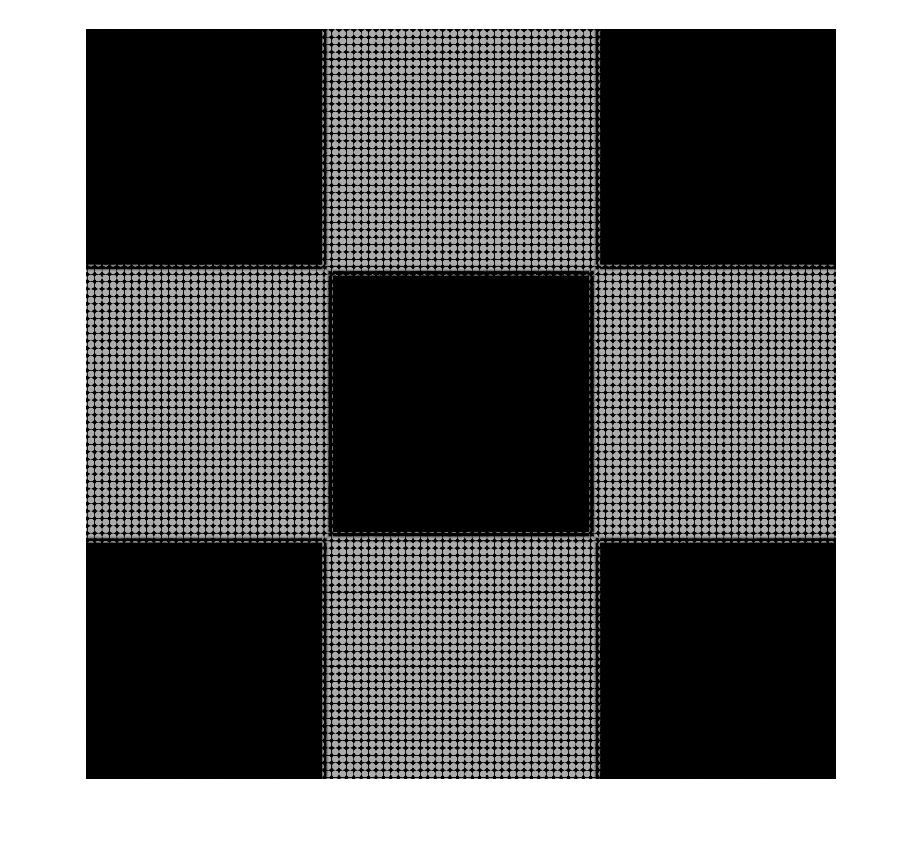

imshow(imgNew)

imwrite(imgNew,['image.tif'])